%% === Setup ===
addpath("C:\Users\JINHWA\Projects\BrainNetworkTDA\ExternalPackages\PH-STAT-main\");


%% === Subject File Paths ===
file_male   = 'C:\Users\JINHWA\Projects\BrainNetworkTDA\Usedata\rfMRI_ts\100206_REST1_LR_AAL_corr_vec.txt';
file_female = 'C:\Users\JINHWA\Projects\BrainNetworkTDA\Usedata\rfMRI_ts\102311_REST1_LR_AAL_corr_vec.txt';

%% === Function: Convert correlation vector into TDA embedding & persistence ===
function [z, D_tensor, Wb_all, Wd_all] = compute_embedding_and_persistence(txt_path, win_size)
    V = readmatrix(txt_path);  % (6670 x 1081)
    n_series = size(V, 2);
    n_points = n_series - win_size + 1;
    D_all = cell(1, n_points);

    for t = 1:n_points
        X = V(:, t:t+win_size-1)';
        D = squareform(pdist(X, 'euclidean'));

        D = double(D);
        D(isnan(D) | isinf(D)) = 999;
        D(1:end+1:end) = 0;
        D = (D + D') / 2;

        D_all{t} = D;
    end

    D_tensor = cat(3, D_all{:});
    z = WS_embed(D_tensor);

    % Compute persistent diagrams
    Wb_all = cell(1, size(D_tensor, 3));
    Wd_all = cell(1, size(D_tensor, 3));
    for t = 1:size(D_tensor, 3)
        [Wb, Wd] = WS_decompose(D_tensor(:, :, t));
        Wb_all{t} = Wb;
        Wd_all{t} = Wd;
    end
end

function d = ws_distance(Wb1, Wd1, Wb2, Wd2, r)
    % Extract birth and death values
    b1 = Wb1(:,3);
    d1 = Wd1(:,3);
    b2 = Wb2(:,3);
    d2 = Wd2(:,3);

    % Sort the values
    b1 = sort(b1);
    d1 = sort(d1);
    b2 = sort(b2);
    d2 = sort(d2);

    % Ensure equal lengths by padding with zeros if necessary
    len = max([length(b1), length(b2), length(d1), length(d2)]);
    b1(end+1:len) = 0;
    b2(end+1:len) = 0;
    d1(end+1:len) = 0;
    d2(end+1:len) = 0;

    % Compute the Wasserstein distance
    d = (sum(abs(b1 - b2).^r) + sum(abs(d1 - d2).^r))^(1/r);
end



%% === Function: Total Wasserstein Distance ===
function L = compute_total_wasserstein_distance(Wb1, Wd1, Wb2, Wd2, r)
    T = numel(Wb1);
    L = 0;
    for t = 1:T
        if isempty(Wb1{t}) || isempty(Wb2{t})
            continue
        end
        d = ws_distance(Wb1{t}, Wd1{t}, Wb2{t}, Wd2{t}, r);  % r typically 2
        L = L + d;
    end
end


%% === Main Execution ===
win_size = 60;


%% === Run for Both Subjects ===
[z_male, D_male, Wb_male, Wd_male]     = compute_embedding_and_persistence(file_male, win_size);
[z_female, D_female, Wb_female, Wd_female] = compute_embedding_and_persistence(file_female, win_size);



% Step 2: Compute Wasserstein Distance
L2 = compute_total_wasserstein_distance(Wb_male, Wd_male, Wb_female, Wd_female, 2);

fprintf("Total Wasserstein distance (L2) between male and female subject: %.4f\n", L2);

Total Wasserstein distance (L2) between male and female subject: 116374.2052


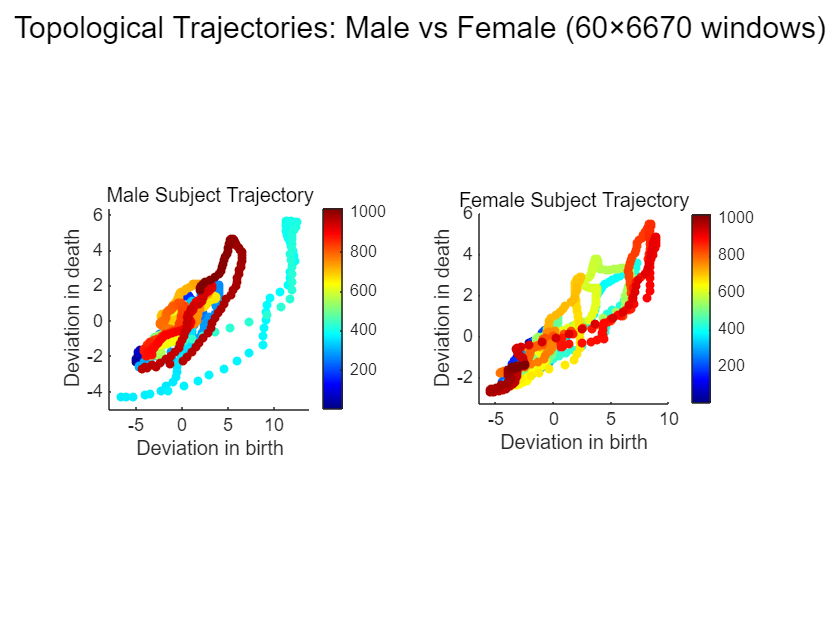

%% === Plot Side-by-Side Trajectories ===
figure;

subplot(1,2,1);
scatter(z_male.x, z_male.y, 20, 1:length(z_male.x), 'filled');
colormap(jet); colorbar;
xlabel('Deviation in birth'); ylabel('Deviation in death');
title('Male Subject Trajectory');
axis square; xlim padded; ylim padded;

subplot(1,2,2);
scatter(z_female.x, z_female.y, 20, 1:length(z_female.x), 'filled');
colormap(jet); colorbar;
xlabel('Deviation in birth'); ylabel('Deviation in death');
title('Female Subject Trajectory');
axis square; xlim padded; ylim padded;

sgtitle('Topological Trajectories: Male vs Female (60×6670 windows)');